
clear all; close all; clc;clf;warning off


workingDir = 'C:\Users\Srisurya\Desktop\Surya_docs\amrita\sem3\19MAT204\projects';
mkdir(workingDir)
mkdir(workingDir,'images')


vid_name='dilu_3.mp4';
%vid_name = 'pexels-allan-mas-5362370.mp4'
a=1/8;
v = VideoReader(vid_name);

Error using VideoReader/initReader (line 734)
The filename specified was not found in the MATLAB path.

Error in audiovideo.internal.IVideoReader (line 136)
            initReader(obj, fileName, currentTime);

Error in 

n_frames = 1;
while hasFrame(v)
    vid = readFrame(v);
    video(:,:,:,n_frames) = imresize(vid, [a*v.Height a*v.Width]);
    n_frames = n_frames+1;
end

im_h=size(video,1);
im_w=size(video,2);
n_frames=n_frames-1;
save('video.mat','video');


vid_mat='video.mat';
% get camera data
video = importdata(vid_mat);
size(video)

ans =    135   240     3   450


for i=1:size(video,4)
    image = im2double( imresize( rgb2gray(video(:,:,:,i)) ,[im_h im_w] ) );
    X(:,i)= reshape(image,[im_h*im_w,1]);
end
size(image)

ans =    135   240


size(X)

ans =        32400         450


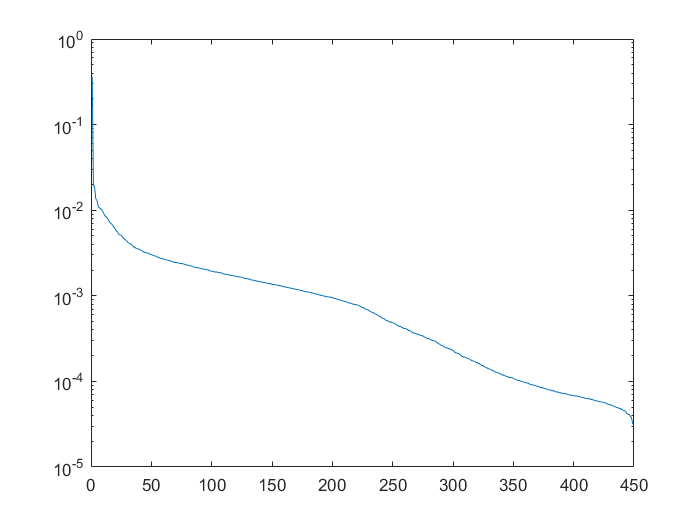

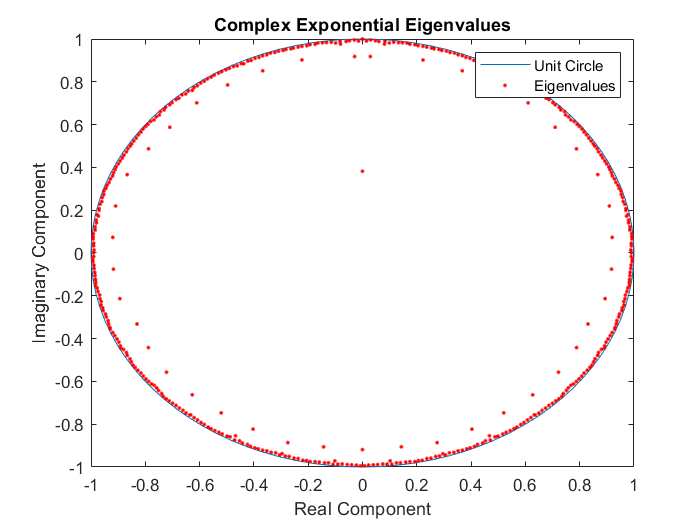

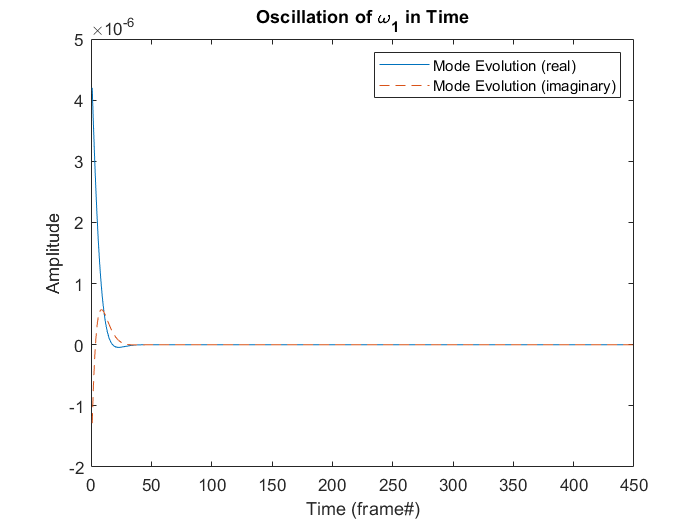

init_range =          0    0.0119


inv_range = 84.2154

Unrecognized function or variable 'Xl'.

Error in try5>mat2fg (line 109)
XS=( Xl - BG );

vid_filter = mat2fg(X,n_frames,v.FrameRate);

A=cat(3,vid_filter,vid_filter,vid_filter);
A=permute(A,[1 3 2]);
A=reshape( A,[im_h im_w 3 n_frames-1]);

% filtered video, with BG removed!
f_vid = (double(video(:,:,:,1:end-1)).*double(A));

for i=1:n_frames-1
    frame = uint8(f_vid(:,:,:,i));
    filename = [sprintf('%03d',i) '.jpg'];
    fullname = fullfile(workingDir,'images',filename);
    imwrite(frame,fullname)
    %imshow(uint8(f_vid(:,:,:,i))); 
end

imageNames = dir(fullfile(workingDir,'images','*.jpg'));
imageNames = {imageNames.name}';
outputVideo = VideoWriter(fullfile(workingDir,'output1'));
outputVideo.FrameRate = v.FrameRate;
open(outputVideo)

for ii = 1:length(imageNames)
   img = imread(fullfile(workingDir,'images',imageNames{ii}));
   
   writeVideo(outputVideo,img)
end
close(outputVideo)


function [vid_filter] = mat2fg(X,n_fram,fr)

X1=X(:,1:end-1); X2=X(:,2:end);
n_frames=size(X1,2);
[u,s,v]=svd(X1,'econ');
S=u'*X2*v*diag(1./diag(s));
[y,S_eigs]=eig(S);
lambda=diag(S_eigs);
dt=1/fr;
w=log(lambda)/(dt);

phi=u*y;

phi_0=phi\u(:,1);
b_e_wt=phi_0.*exp(w*(1:n_frames));
u_dmd=phi*b_e_wt;


figure(1)
title('Normalized Spectrum of X1 SVD Modes')
xlabel('SVD Mode')
ylabel('Relative Mode Strength')
semilogy(diag(s)/sum(diag(s)))


figure(2)
plot(cos(0:pi/50:2*pi),sin(0:pi/50:2*pi),imag(lambda),real(lambda),'r.')
title('Complex Exponential Eigenvalues')
xlabel('Real Component')
ylabel('Imaginary Component')
legend('Unit Circle','Eigenvalues')


figure(3)
plot(real(b_e_wt(1,1:n_fram-1))), hold on
plot(imag(b_e_wt(1,1:n_fram-1)),'--')
title('Oscillation of \omega_1 in Time')
xlabel('Time (frame#)')
ylabel('Amplitude')
legend('Mode Evolution (real)','Mode Evolution (imaginary)')


BG = abs(u_dmd);
init_range = double([min(BG(:)) max(BG(:))])
inv_range = 1/(init_range(2)-init_range(1))
BG = imlincomb(inv_range, BG, -init_range(1)*inv_range, 'double');
XS=( X1 - BG );

vid_filter=abs(XS)>0.18;

end


